% AE 6353 - Homework 1 
% Lauren Forcey
% 8/29/25

% =============================
% Problem 1

% assumptions: moon and earth co-orbit their barycenter
% in circular orbits using the two body approx

% used this vid to visualize: 
% https://www.youtube.com/watch?v=7hMfCCqSdFc&t=21s

% planet masses
mearth = 5.9722e24; % kg
mmoon = 7.3477e22;  % kg

% distance between earth and moon
dEM = 3.844e5; % km

% distance from earth to barycenter
bc_loc = (mmoon/(mmoon + mearth))* dEM;

disp('1a: initial position coordinates at t=0')

1a: initial position coordinates at t=0


% distance from earth's center to barycenter
re_EMI = [bc_loc,0]

re_EMI = 	1.0e+03 *

    4.6719         0


% distance from moon's center to barycenter
rm_EMI = [-(dEM-bc_loc),0]

rm_EMI = 	1.0e+05 *

   -3.7973         0



%   m ------------ bc e 

Tem = 2.3606e6 % lunar period around earth

Tem = 2360600


% b: find initial velocity coordinates in EMI frame

% ang vel = 2pi/ T
% earth and moon orbital period equal about barycenter
wm = 2*pi / Tem;
we = 2*pi / Tem;

disp('1b: initial velocity coordinates')

1b: initial velocity coordinates


vm_EMI = wm*rm_EMI

vm_EMI =    -1.0107         0


ve_EMI = we*re_EMI

ve_EMI =     0.0124         0



% transform into the earth centered inertial frame
% origin: CM of earth

disp('1c: r and v in ECI')

1c: r and v in ECI


re_ECI = [0,0]

re_ECI =      0     0


rm_ECI = [-dEM,0]

rm_ECI =      -384400           0



ve_ECI = 2*pi*re_ECI/Tem % zero since origin

ve_ECI =      0     0


vm_ECI = 2*pi*rm_ECI/Tem % nonzero since r >0

vm_ECI =    -1.0232         0



% what is the shape and period of the orbit trajectory

% semi major axis = rp = rm_ECI
disp('1d: calculated period')

1d: calculated period


T_calc = (2*pi/sqrt(3.986e5))*(norm(rm_ECI))^(3/2)

T_calc = 2.3718e+06

T_days = T/60/60/24;


% a_EM and period
disp('1e:a_EM and T_EM')

1e:a_EM and T_EM


G = 6.67e-20; % km^3/kg s^2
a_EM = dEM % circular

a_EM = 384400

mu_EM = G*(mearth+mmoon);
T_EM = (2*pi/sqrt(mu_EM))*(a_EM)^(3/2)

T_EM = 2.3581e+06


% a_EM and period
disp('1f:a_EM and T_EM without moon')

1f:a_EM and T_EM without moon


G = 6.67e-20; % km^3/kg s^2
a_EM = dEM % circular

a_EM = 384400

mu_EM2 = G*(mearth);
T_EM2 = (2*pi/sqrt(mu_EM2))*(a_EM)^(3/2)

T_EM2 = 2.3726e+06



% g find the % difference in answers e and f
disp('1f: percent difference')

1f: percent difference


perdiff = (abs(T_EM-T_EM2)/((T_EM + T_EM2)/2))*100

perdiff = 0.6114



% =============================
% Problem 2

disp('2: checking if same object')

2: checking if same object


disp('answer: no, direction of ang mom not conserved')

answer: no, direction of ang mom not conserved


mu_moon = 4902.8; % km^3/s^2

% initial
rMCI0 = [-1085.9, 2659.8, 1085.9];
vMCI0 = [-0.94760,-0.77371,0.94760];

hMCI0 = cross(rMCI0,vMCI0);
h0mag = norm(hMCI0);

% after 4 hours
rMCI4 = [-4420.3,-6449.9,-3475.6];
vMCI4 = [0.33809,-0.27958,-0.41117];

hMCI4 = cross(rMCI4,vMCI4);
h4mag = norm(hMCI4);

hmagdiff = (h4mag-h0mag)/((h0mag+h4mag)/2) * 100

hmagdiff = 1.8766


% angle between the angular momentum vectors
theta = acosd(dot(hMCI0,hMCI4)/(h0mag*h4mag))

theta = 41.9083


r0mag = norm(rMCI0);
r4mag = norm(rMCI4);
v0mag = norm(vMCI0);
v4mag = norm(vMCI4);

% energy
e0 = 0.5*v0mag^2 - mu_moon/r0mag;
e4 = 0.5*v4mag^2 - mu_moon/r4mag;

% percent diff of total energy
ediff = (abs(e0-e4))/(abs(e0+e4)/2)*100

ediff = 1.7354


% ==============
% Problem 3

% see handwritten solutions
% table complete.

% =============================
% Problem 4

% references: 
% https://www.math.umd.edu/~petersd/460/html/ode45_demo2.html
% https://www.math.purdue.edu/~walther/teach/MA366labs/ode45.pdf

% given: initial conditions and propagation time
ri = [2120.3; 7642.6;-3964.1];  % km
vi = [-5.4694;-5.0287;-4.4382]; % km/s
tprop = 43082; % propagation time

% making col vector w all ICs
x0 = [ri;vi];

% propagaton time
t0 = 0;
tf = tprop;

% solve with ode45
options = odeset('RelTol',1e-12,"AbsTol",1e-12);
[t, state] = ode45('eqnofmotion',[t0,tf], x0, options);

% PART B: grab the final position and velocity vectors
% last row = state at tf
disp('4b: final position and velocity vecs:')

4b: final position and velocity vecs:


rf = state(end,1:3) % first 3 vals in the last row

rf = 	1.0e+03 *

    2.0568    7.5840   -4.0154


vf = state(end,4:6) % last 3 vals in the last row

vf =    -5.4833   -5.0795   -4.4116



% PART A: plotting it in 3D
% Extract components of the array
% first 3 cols are pos, second 3 are vel
disp('4a: plot in 3D')

4a: plot in 3D


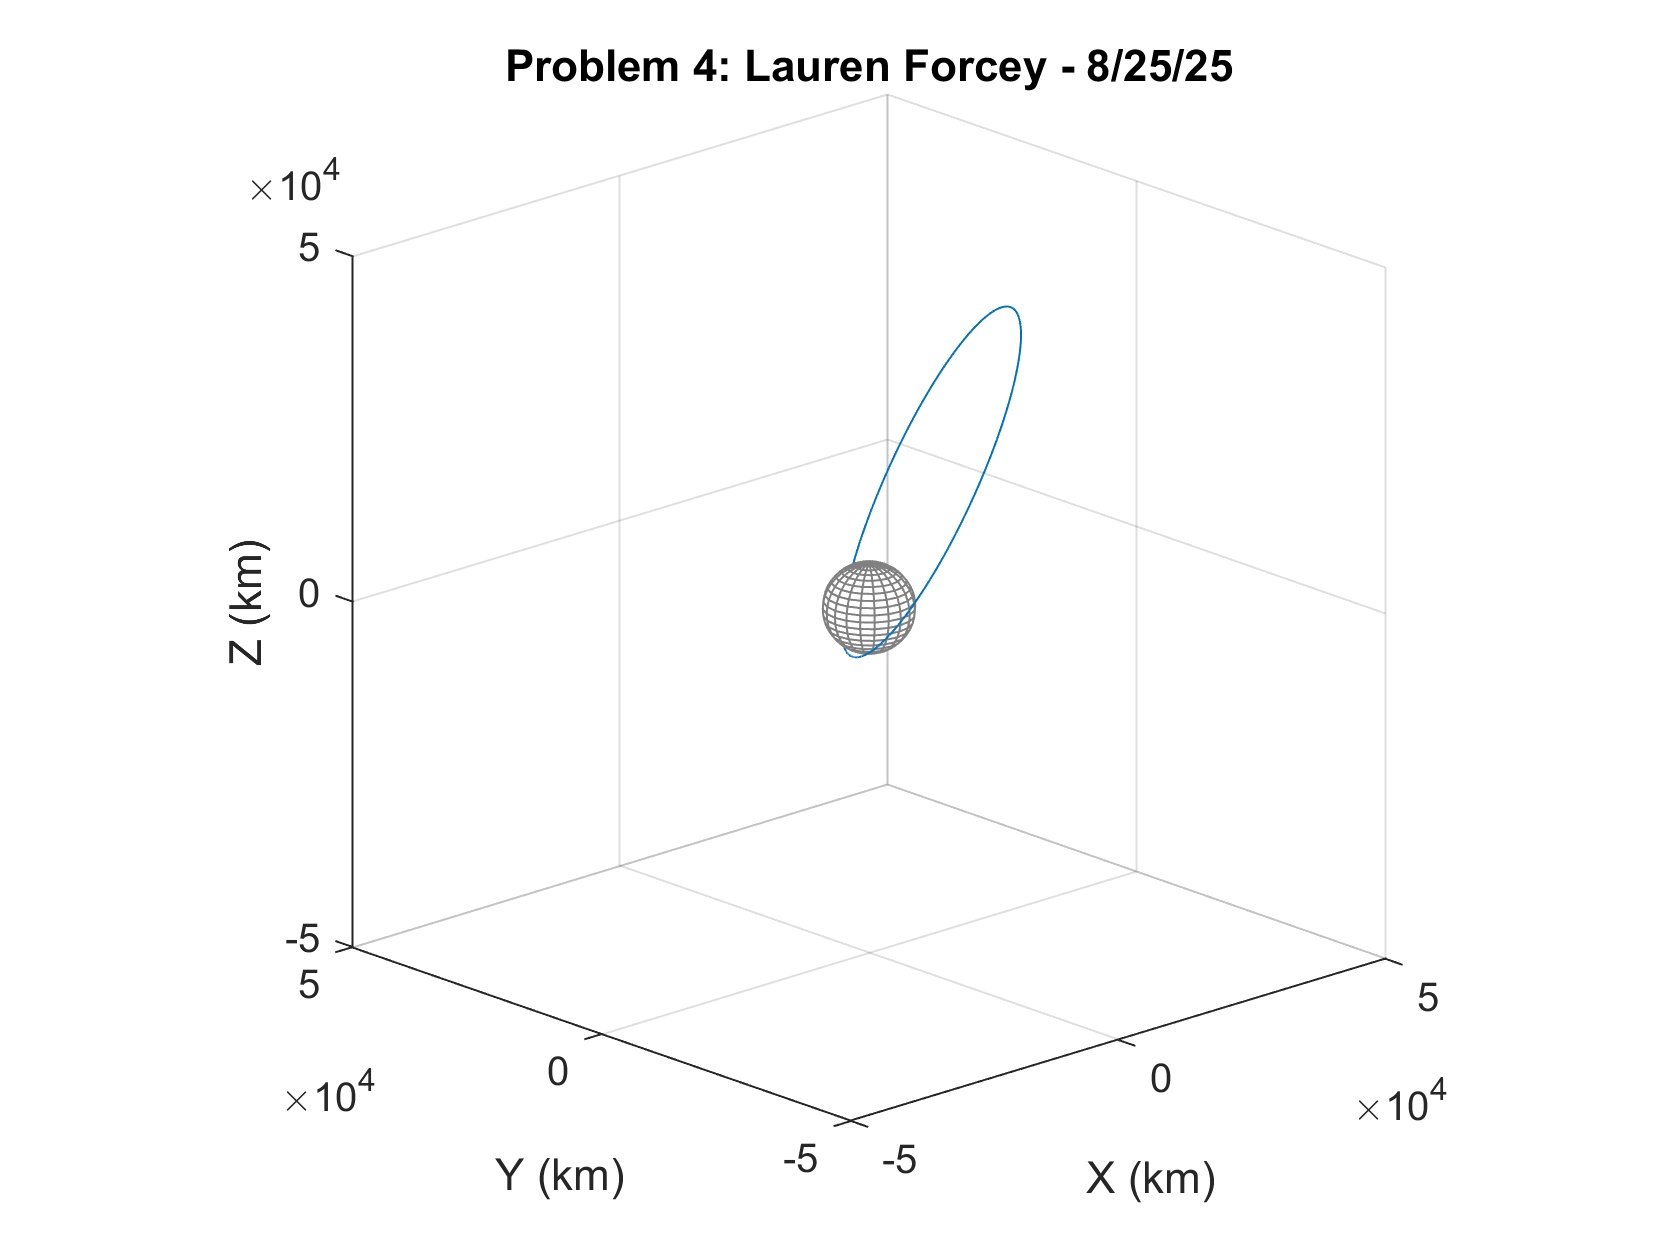


% state vec : col 1 = x, col 2 = y, col 3 = z
plot3(state(:,1), state(:,2), state(:,3))
title({'Problem 4: Lauren Forcey - 8/25/25'})
xlabel('X (km)')
ylabel('Y (km)')
zlabel('Z (km)')

% code block from hw to plot the earth as a sphere
% (copy pasted)
figure(1)
npanels=20;
erad = 6378.1; % equatorial radius (km)
prad = 6356.8; % polar radius (km)
axis(5e4*[-1 1 -1 1 -1 1]);
view(-43,19);
grid;
hold on;
axis vis3d;
[xx,yy,zz ] = ellipsoid(0, 0, 0, erad, erad, prad,npanels);
globe = surf(xx, yy, -zz, 'FaceColor', 'w', 'EdgeColor',0.5*[1 1 1]);
hold off;


% =============================